This file develops a fuzzy logic controller that utilizes two inputs (psi and psi dot), each of which have three membership functions. Five singleton outputs exist for the fuzzy rule base. This file was used to prove that we could greatly simplify the number of parameters and still control the system as compared to the two other proposed FIS structures.

clear;

%system dynamics

m_pend = 0.5;       %kg
m_cart = 0.2;       %kg
I_pend = 0.1;       %kg*m^2
l = 0.03;           %from rotation point to COM
g = 9.8;            %m/s^2
f = 0.01;            %frictional coefficient
K_T = 0.11;          %N*m/A
R_motor = 10;        %ohm
r_wheel = 0.0335;    %m

% SS matrices

A22 = -(I_pend+m_pend*l^2)*f / (I_pend*(m_cart + m_pend)+m_cart*m_pend*l^2);
A23 = (m_pend^2*g*l^2) / (I_pend*(m_cart+m_pend)+m_cart*m_pend*l^2);
A42 = (-m_pend*l*f) / (I_pend*(m_cart+m_pend)+m_cart*m_pend*l^2);
A43 = (m_pend*g*l*(m_cart+m_pend)) / (I_pend*(m_cart+m_pend)+m_cart*m_pend*l^2);

A = [ 0 1 0 0;
    0 A22 A23 0;
    0 0 0 1;
    0 A42 A43 0];

B2 = (I_pend+m_pend*l^2)/(I_pend*(m_cart+m_pend)+m_cart*m_pend*l^2);
B4 = (m_pend*l) / (I_pend*(m_cart+m_pend)+(m_cart*m_pend*l^2));

B = [0;
    B2;
    0
    B4];

C = [1 0 0 0;
    0 0 1 0];

D = [0;
    0];

[b,a] = ss2tf(A,B,C,D); %implicit ZoH

%create SS and TF model

ts = 0.005; %s

sys_cont = ss(A,B,C,D);
sys_disc = c2d(sys_cont, ts);
A = sys_disc.A; B = sys_disc.B; C = sys_disc.C; D = sys_disc.D;

N = negative, Z = zero, P = positive

%input

%psi
N_psi = -7; 
Z_psi = 0;
P_psi = 7;

%psi_d
N_psi_d = -.2;
Z_psi_d = 0;
P_psi_d = .2;

%output
NB = -255;
NS = -60;
Z = 0;
PS = 60;
PB = 255;

%only using error in psi and psi_d, not x_d error...

states_psi = [N_psi,Z_psi,P_psi];
states_psi_d = [N_psi_d,Z_psi_d,P_psi_d];

Control rule is set up in 2D as...

                              PSI error

                            N    Z    P

                    N

PSI_D          Z

Error            P

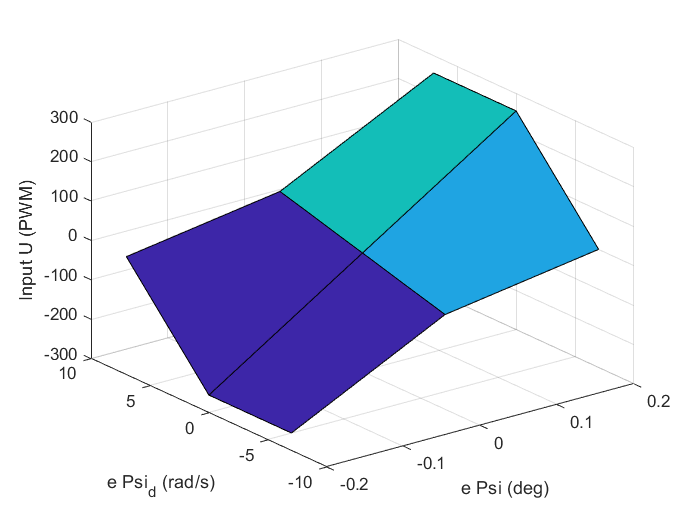

%define control rule and visual manifold
[e_psi, e_psi_d] = meshgrid(states_psi_d, states_psi);
control_rule = [NB NS Z;
                NB Z PB;
                Z PS PB];
surf(e_psi, e_psi_d, control_rule)
xlabel('e Psi (deg)')
ylabel('e Psi_d (rad/s)')
zlabel('Input U (PWM)')

%Fuzzification constants

%CONSTANTS FOR PSI ERROR
c_N_psi = N_psi; a_N_psi = -.15;  %sigmoid
c_Z_psi = Z_psi; sd_Z_psi = .4;   %gaussian
c_P_psi = P_psi; a_P_psi = .15;   %sigmoid

%CONSTANTS FOR PSI_D ERROR
c_N_psi_d = N_psi_d; a_N_psi_d = -1.5;  %sigmoid
c_Z_psi_d = Z_psi_d; sd_Z_psi_d = .15;  %gaussian
c_P_psi_d = P_psi_d; a_P_psi_d = 1.5;   %sigmoid


%run through test cases to see if membership amount seem reasonable!

%TEST CASES FOR PSI
%slightly negative angle
sigmoid(-2,c_N_psi,a_N_psi)

ans = 0.3208

gaussian(-2,c_Z_psi,sd_Z_psi)

ans = 3.7267e-06

%large positive angle
sigmoid(11,c_P_psi,a_P_psi)

ans = 0.6457

gaussian(11,c_Z_psi,sd_Z_psi)

ans = 6.0590e-165


%TEST CASES FOR PSI_D
%slightly negative angular velocity
sigmoid(-.3,c_N_psi_d,a_N_psi_d)

ans = 0.5374

gaussian(-.3,c_Z_psi_d,sd_Z_psi_d)

ans = 0.1353

%large positive angular velocity
sigmoid(3,c_P_psi_d,a_P_psi_d)

ans = 0.9852

gaussian(3,c_Z_psi_d,sd_Z_psi_d)

ans = 1.3839e-87

T = 4000;
time_step = 0.005;
time = linspace(1,T*time_step, T);
%zero reference for impulse response
ref = [zeros(1,length(time)); zeros(1,length(time)); zeros(1,length(time)); zeros(1,length(time))];

%constriants
Vmax = 7;
Vmin = -7;

%initial conditions
X = [0;0;0;0];
PWMact = 0.0;
UAct = 0.0; 
err = zeros(4,1);

tic
for i = 1:(T)
    XAct(i,:) = X;
    
    %get errors
    err = ref(:,i) - X; 
    
    %convert error to degrees...
    err(3) = err(3)*180/pi;
    
    %input curve evaluation...
    
    %psi error
    u_N_psi = sigmoid(err(3),c_N_psi,a_N_psi); 
    u_Z_psi = gaussian(err(3),c_Z_psi,sd_Z_psi); 
    u_P_psi = sigmoid(err(3),c_P_psi,a_P_psi); 
    %array of psi errors
    u_psi = [u_N_psi,  u_Z_psi, u_P_psi];

    %psi dot error
    u_N_psid = sigmoid(err(4),c_N_psi_d,a_N_psi_d); 
    u_Z_psid = gaussian(err(4),c_Z_psi_d,sd_Z_psi_d); 
    u_P_psid = sigmoid(err(4),c_P_psi_d,a_P_psi_d); 
    %array of psi dot errors
    u_psid = [u_N_psid,u_Z_psid, u_P_psid];
    
    %create matrix to store rule evaluation
    ruleEvals = zeros(numel(u_psi), numel(u_psid));

    %rule evaluation from current states
    for ii = 1:numel(u_psi)
        for j = 1:numel(u_psid)
            ruleEvals(j,ii) = u_psi(ii) * u_psid(j);
        end
    end 
    
    %defuzzification
    weightedSum = sum((ruleEvals .* control_rule), 'all');
    defuzzOutput = weightedSum / sum(ruleEvals,'all');
    
    %fuzzy logic search to get PWM -> V -> U
    voltage = defuzzOutput / 255 * Vmax;
    %check for voltage saturation -- shouldn't exist because using fuzzy
    %logic pwm rules that account for saturation. But play it safe.
    voltage = min(Vmax,max(Vmin, voltage));
    %convert voltage to force, U
    U = 2 * K_T / (R_motor * r_wheel) * voltage;
    
    %update states
    X = A*X + B*U;
    
    %add impulses at certain steps - modeled only as angular velocity
    %component
    if i == 400 
        X = X + [0;0;0;.4];
    end
        
    %store for graphing
    PWMact = [PWMact defuzzOutput];
    UAct = [UAct U]; 

end
toc

Plot Performance

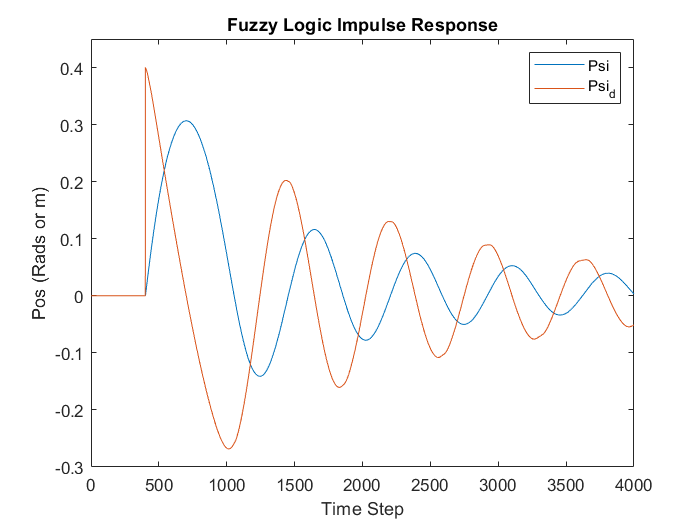

figure(1)
plot([1:T],XAct(:,3),[1:T],XAct(:,4)); 
ylim([-.3,.45]);
xlabel("Time Step");
ylabel("Pos (Rads or m)");
title("Fuzzy Logic Impulse Response")
legend("Psi", "Psi_d")

Plot Input Force

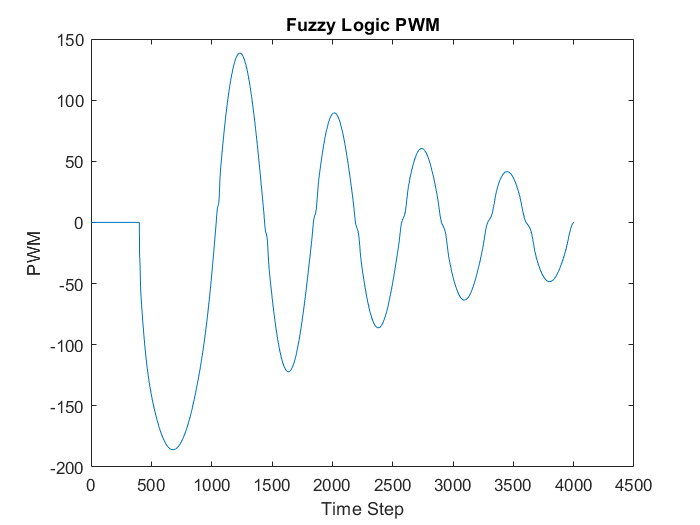

x = linspace(1,T+1, T+1);

figure(2)
plot(x, PWMact)
xlabel("Time Step");
ylabel("PWM");
title("Fuzzy Logic PWM")

DEFINE FUNCTIONS

function f = sigmoid(x, c, a)
    f = 1 / (1 + (exp(-a*(x-c))));
end
function f = gaussian(x, c, sd)
    f = exp((-1/2)*((x-c)/sd)^2);
end